1. Read the files, determine the starting time:

NB! If error while running, most probably there are extra files in the dir!

% CHANGES:
% 1: Time delay is averaged amongst the files
% 

%TDTR_matrix_to_struct
clear;
% filename = ['Quartz_N4_June2.mat'];
% 11.01.2023: changed to the cycle %

% myDataDir = '\data';    % enter manually

%tmpDir = pwd;
%tmpDir = strcat( tmpDir, myDataDir );
tmpDir = 'Z:\ForMATLAB\data';
tmpDir = 'Z:\DirDusseldorfAirport'

tmpDir = 'Z:\DirDusseldorfAirport'


fNames = dir(strcat(tmpDir, '\*.mat')) ;   % you are in the folder of files 

fprintf("\nTotal *.mat-files in 'data' folder: %d.\n",length(fNames))


Total *.mat-files in 'data' folder: 1.



% PART 1: get zero time:
tmpAZ = zeros(length(fNames),1);
tmpAZind = zeros(length(fNames),1);

for currFind = 1:length(fNames)
    filename = fNames(currFind).name;

    data = load(strcat(tmpDir,'\',filename));
    data = data.Data;

    if isstruct(data)
        structData = struct();
        structData.stagePosition = data.StagePosition;%.Data(:,1);
        structData.tdelay = data.tdelay; %.Data(:,2); % in ps
        structData.Vin = data.Vin; %.Data(:,3); %in uV
        structData.Vout = data.Vout; %.Data(:,4); % in uV
        structData.Ratio = data.Ratio; %.Data(:,5);
        structData.Vdet = data.Vdet;
    
        Data = structData;
    
    elseif ismatrix(data)
        Data.stagePosition = data(:,1);
        Data.tdelay = data(:,2);
        Data.Vin = data(:,3);
        Data.Vout = data(:,4);
        Data.Ratio = data(:,5);
        Data.Vdet = ones(length(data.Data(:,5)),1);
    end

    %%% Apr. 19 >>> %%%
    % Remove 'NaN' values: %
    tmpBefore = length(Data.stagePosition);
    Data = struct2table(Data);
    Data = Data(~any(ismissing(Data),2),:);
    Data = table2struct(Data,'ToScalar',true);
    tmpAfter = length(Data.stagePosition);
    fprintf("Deleted %d entries for file No. %d.\n", round(tmpBefore-tmpAfter),currFind);
    %%% <<< %%%



    %automatically shift the tdelay zero to peak position
    [tmpAZ(currFind),tmpAZind(currFind)] = max(abs(diff(Data.Vin)));
end    % for currFind = 1:length(fNames)

Deleted 1 entries for file No. 1.



%print(tmpAZ);
%print(tmpAZind);
fprintf('tmpAZ: [%s]\n', join(string(tmpAZ), ','));

tmpAZ: [69.207]


fprintf('mean value of <tmpAZ>: %f',mean(tmpAZ));

mean value of <tmpAZ>: 69.207029


fprintf('tmpAZind: [%s]\n', join(string(tmpAZind), ','));

tmpAZind: [14]


% approx_zero,az_idx

If the above output is consistent, get the mean shifted value

tmpMEANdelayINDEX = mean(tmpAZind)

tmpMEANdelayINDEX = 14

% tmpMEANdelayINDEX = 28;
% <<< override, if needed. %
tmpMEANdelayINDEX = round(tmpMEANdelayINDEX)

tmpMEANdelayINDEX = 14

if tmpMEANdelayINDEX < 1
    tmpMEANdelayINDEX = 1;
end
while tmpMEANdelayINDEX > length(Data.stagePosition)
    tmpMEANdelayINDEX = tmpMEANdelayINDEX - 1;
end
% Data.tdelay = (Data.stagePosition - Data.stagePosition(az_idx)).*(2*12.5e-6*1e12)./3e8; %in ps

The time delay will be subtracted when passing the data to the AutoSetPhase function (below):

tAutoPhaseMin = -20; % ps
tAutoPhaseMax = +80; % ps
fprintf("Using the following window for phase auto setting: %f to %f.", ...
    tAutoPhaseMin,tAutoPhaseMax);

Using the following window for phase auto setting: -20.000000 to 80.000000.


filename = fNames(1).name

filename = 'a01_SimpleSurface_200623_204333.mat'

data = 1.0e+04 *

       NaN       NaN       NaN       NaN       NaN       NaN
   -1.3000   -0.0092    0.0002   -0.0001    0.0002    0.0354
   -1.2900   -0.0083    0.0002   -0.0001    0.0002    0.0355
   -1.2800   -0.0075    0.0002   -0.0001    0.0002    0.0354
   -1.2700   -0.0067    0.0002   -0.0001    0.0002    0.0354
   -1.2600   -0.0058    0.0002   -0.0001    0.0002    0.0355
   -1.2500   -0.0050    0.0002   -0.0001    0.0002    0.0355
   -1.2400   -0.0042    0.0002   -0.0001    0.0002    0.0354
   -1.2300   -0.0033    0.0002   -0.0001    0.0002    0.0355
   -1.2200   -0.0025    0.0002   -0.0001    0.0002    0.0355


Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: 0.00 degrees
 mean difference between [-20 0] and [0 80] ps: 0.218

residual = 1.0182e-05, delphase = 0.17051

Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: -0.36 degrees
 mean difference between [-20 0] and [0 80] ps: 0.000



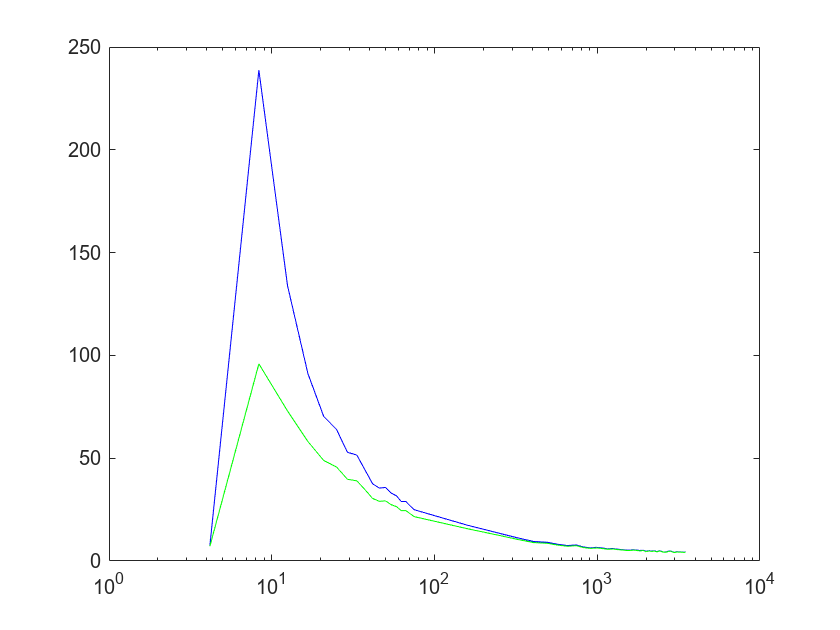


arrNewFiles = strings(length(fNames),1);
phaseShiftsAutoApplied = zeros(length(fNames),1);


%filename = 'f07_SampleN4_phase0_250322_230743.mat';
%filename = 'f06_SampleN3_phase0_250322_224312.mat';
%filename = 'struct_test_data2_SHIFTED.mat'
%filename = '25_f05_SampleN2_phase0_250322_220940.mat';
%filename = 'sio2_test_SHIFTED.mat';

for currFind = 1:length(fNames)
    filename = fNames(currFind).name;

    % data = load(strcat(tmpDir,'\',filename));
    data = load([tmpDir '\' filename]);
    data = data.Data;

    if isstruct(data)
        structData = struct();
        structData.stagePosition = data.StagePosition;%.Data(:,1);
        structData.tdelay = data.tdelay; %.Data(:,2); % in ps
        structData.Vin = data.Vin; %.Data(:,3); %in uV
        structData.Vout = data.Vout; %.Data(:,4); % in uV
        structData.Ratio = data.Ratio; %.Data(:,5);
        structData.Vdet = data.Vdet;
    
        Data = structData;
    
    elseif ismatrix(data)
        Data.stagePosition = data(:,1);
        Data.tdelay = data(:,2);
        Data.Vin = data(:,3);
        Data.Vout = data(:,4);
        Data.Ratio = data(:,5);
        Data.Vdet = ones(length(data.Data(:,5)),1);
    end

    
    %% USE THE MANUAL (SINGLE) SHIFT FOR THE ZERO POS
    Data.tdelay = (Data.stagePosition - Data.stagePosition(tmpMEANdelayINDEX)).*(2*12.5e-6*1e12)./3e8; %in ps
    
    % Plotting is removed from here %
    
    prefix = strsplit(filename,'.');
    arrNewFiles(currFind) = [prefix{1} '_prep.mat'];
    
    tmp = strcat(tmpDir, '\', arrNewFiles(currFind));
    
    save(tmp,"Data");
    % new_file = [prefix{1} '_prep.mat'];
    % save(new_file,"Data")
    
    
    %%Automatically run AutoSetPhase() to fix phase shift emerging from
    %%instrumentation
    
    phaseCurr = 0.0;    % for <AutoSetPhase> output...
    % AutoSetPhase(0, arrNewFiles(currFind),[-20 80])
    [notUsed1, phaseCurr, notUsed2] = AutoSetPhase( 0, convertStringsToChars(tmp), [tAutoPhaseMin tAutoPhaseMax]);

    phaseShiftsAutoApplied(currFind) = phaseCurr

    if exist(tmp, 'file')==2
        delete(tmp);
    end

end    % for currFind = 1:length(fNames)


fprintf("Done!");

Now, check the phase shifts:

phaseShiftsAutoApplied

phaseShiftsAutoApplied = 0


% Output the files' names:
tmp = strings(length(fNames),1);
for jj = 1 : length(fNames)
    tmp(jj) = fNames(jj).name;
end

% fprintf('File names: [%s]\n', join(tmp, ','));
fprintf('File names:\n');

File names:


tmp

tmp = "a01_SimpleSurface_200623_204333.mat"


fprintf("Mean phase shift: %f.\n",mean(phaseShiftsAutoApplied));

Mean phase shift: 0.000000.


Choose the phase shift to be applied:

decidedPhaseShiftDEG = -4.00; % degrees
fprintf("Using the phase shift of\n %f degrees.",decidedPhaseShiftDEG);

Using the phase shift of
 -4.000000 degrees.

Apply the phase shifts manually, + output for processing...

for currFind = 1:length(fNames)
    filename = fNames(currFind).name;

    % data = load(strcat(tmpDir,'\',filename));
    data = load([tmpDir '\' filename]);
    data = data.Data;

    if isstruct(data)
        structData = struct();
        structData.stagePosition = data.StagePosition;%.Data(:,1);
        structData.tdelay = data.tdelay; %.Data(:,2); % in ps
        structData.Vin = data.Vin; %.Data(:,3); %in uV
        structData.Vout = data.Vout; %.Data(:,4); % in uV
        structData.Ratio = data.Ratio; %.Data(:,5);
        structData.Vdet = data.Vdet;
    
        Data = structData;
    
    elseif ismatrix(data)
        Data.stagePosition = data(:,1);
        Data.tdelay = data(:,2);
        Data.Vin = data(:,3);
        Data.Vout = data(:,4);
        Data.Ratio = data(:,5);
        Data.Vdet = ones(length(data.Data(:,5)),1);
    end

    
    %% USE THE MANUAL (SINGLE) SHIFT FOR THE ZERO POS
    Data.tdelay = (Data.stagePosition - Data.stagePosition(tmpMEANdelayINDEX)).*(2*12.5e-6*1e12)./3e8; %in ps
    
    % Plotting is removed from here %
    
    prefix = strsplit(filename,'.');
    % ALREADY DEFINED ABOVE: 
    % arrNewFiles(currFind) = [prefix{1} '_prep.mat'];
    tmp = strcat(tmpDir, '\', arrNewFiles(currFind));
    
    % ALREADY SAVED ABOVE:
    % save(tmp,"Data");
    % new_file = [prefix{1} '_prep.mat'];
    % save(new_file,"Data")
    
    
    %% SETTING THE PHASE MANUALLY:
    
    [Data.Vin, Data.Vout] = VKorn_PhaseShift(decidedPhaseShiftDEG, ...
        Data.Vin, Data.Vout);

    Data.Ratio = - Data.Vin ./ Data.Vout;

    tmp = strcat(prefix{1}, '_FIN.mat');
    tmp = strcat(tmpDir, '\', tmp);
    
    % 20.06.2023:
    % remove NaNs again (no idea why):
    % Remove 'NaN' values: %
    tmpBefore = length(Data.stagePosition);
    Data = struct2table(Data);
    Data = Data(~any(ismissing(Data),2),:);
    Data = table2struct(Data,'ToScalar',true);
    tmpAfter = length(Data.stagePosition);
    fprintf("Deleted %d entries for file No. %d.\n", round(tmpBefore-tmpAfter),currFind);
    %%% <<< %%%
    
    save(convertStringsToChars(tmp),"Data")
    
    filename_short = (strsplit(tmp, '.mat')); % take filename w/o extension
    filename_short = string(filename_short(1));
    filename_short = strcat(filename_short, ".dat");

    writetable(struct2table(Data), filename_short);

end    % for currFind = 1:length(fNames)

fprintf("Done (setting manual phase)!");

Done (setting manual phase)!

Plotting:

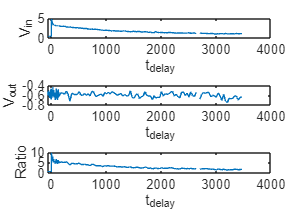

%%%
figure;
subplot(3,1,1)
plot(Data.tdelay,Data.Vin)
ylabel('V_{in}')
xlabel('t_{delay}')
subplot(3,1,2)
plot(Data.tdelay,Data.Vout)
ylabel('V_{out}')
xlabel('t_{delay}')
subplot(3,1,3)
plot(Data.tdelay,Data.Ratio)
ylabel('Ratio')
xlabel('t_{delay}')

%%%

..

%